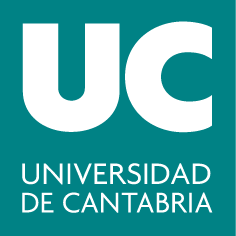

#### ***Grado en Ingeniería ****de Tecnologías de Telecomunicación*

## **G283: Cálculo II**

# **Práctica 6: Integrales de Superficie de Campos Escalares**

*Dpto. Matemática Aplicada y Ciencias de la Computación*

### Objetivos	

- Profundizar en la comprensión de la integral de superficie de un campo escalar mediante la aplicación al cálculo de áreas. 

- Utilizar representaciones gráficas como apoyo para entender las definiciones y las propiedades de la integral de superficie.

- Hallar el valor medio de un campo escalar sobre una superficie, utilizando cálculo simbólico y representar los puntos de dicha superficie donde se alcanza el valor medio.

### Resumen teórico

#### Diferencial de superficie

Se define el elemento $dS$ como un parche infinitesimal de superficie, cuya proyección sobre los planos coordenados en cada punto es:


$$dS= \frac{dxdy}{|cos (\gamma)|}=\frac{dydz}{|cos (\alpha)|}=\frac{dxdz}{|cos (\beta)|}$$


siendo $(cos(\alpha), cos(\beta), cos(\gamma))$ los cosenos directores del vector normal a la superficie en dicho punto.

Los cosenos directores se relacionan con el módulo del vector normal al plano tangente a la superficie en ese punto ($\vec{N}$). En particular, si usamos como plano de proyección el plano $XOY$:

$|\vec{n}\cdot \vec{k}|=|cos(\gamma)|$, donde $\vec{n}=\frac{\vec{N}}{| \vec{N}|}$ es el vector normal unitario.

Como $\vec{N}=\pm(-f'_{x}, -f' _{y}, 1)$ y $\vec{k}=(0,0,1)$, se tiene que $|cos(\gamma)|=\frac{1}{|\vec{N}|}$

Por lo que el diferencial de superficie es: $dS=\sqrt{(f'_{x})^2 + (f'_{y})^2 +1} dxdy$

Se razona de forma análoga para los otros dos planos coordenados.

En el caso de expresar el vector de posición en forma paramétrica (p.ej. usando coordenadas cilíndricas o esféricas): 


$$\vec{r}(u,v)=x(u,v)\vec{i}+y(u,v)\vec{j}+z(u,v)\vec{k}$$


El vector normal unitario al plano tangente en un punto de la superficie y el diferencial de superficie se calculan:


$$\vec{n}=\pm\frac{\vec{r'_{u}}\times \vec{r'_{v}}}{\Big|\vec{r'_{u}}\times \vec{r'_{v}}\Big|}$$
            
$$dS=\Big|\vec{r'_{u}}\times \vec{r'_{v}}\Big| dudv$$


#### Aplicaciones de las integrales de superficie de campos escalares


$$\text{Área(S)}=\int\int_{S}dS$$
        
$$\text{Temperatura media}=\frac{\int\int_{S}T(x, y, z) dS}{\text{Área(S)}}$$


### Comandos útiles

#### Comandos para representaciones en el espacio

- `quiver3(X, Y, Z, U, V, W): `Dibuja los vectores escalados de componentes U, V, W con flechas que tienen su origen en los puntos de coordenadas X, Y, Z. Las matrices X, Y, Z, U, V, W deben tener el mismo tamaño. Si se añade como quinto argumento 0, los vectores que se representan no se escalan, es decir, la longitud de las flechas es el valor real del módulo de los vectores. Ejemplo:

[X,Y] = meshgrid(-2:.2:2,-1:.15:1);
Z = X.^2+Y.^2;
U=2*X; V=3*Y; W=Z;
quiver3(X, Y, Z, U, V, W)

- `surf(X,Y,Z,C)`: Representa el gráfico de superficie de la función con los colores especificados en C (este último parámetro se puede ignorar).

- `plot3(X, Y, Z, S)`: Dibuja las curvas o el conjunto de puntos (X,Y,Z) donde X, Y y Z son vectores fila y S son las opciones de dibujo (este último parámetro se puede ignorar). 

- `view(az, el)`: Controla el punto de vista de una representación con diferentes parámetros. Sitúa el punto de vista de la figura en el indicado por los ángulos az (azimutal) y el (ángulo de elevación sobre el plano z=0), expresados en grados. view(2) ó view(0,90) sirven para recuperar la vista en 2-D.

#### Comando para crear matrices especiales

- `zeros(M, N)`: Crea una matriz MxN formada por ceros. Ejemplo: 

a = linspace(0, 2*pi, 6);
zeros(size(a)) % matriz de ceros del mismo tamaño que a

- ` ones(M, N)`: Crea una matriz MxN formada por unos. Es útil para crear matrices con un valor repetido. Ejemplos: 

ones(size(a))
3*ones(size(a))

###  Ejercicios resueltos

**1. Cálculo del diferencial de superficie, los vectores normales y el área de la superficie.**

Determinar el elemento diferencial de superficie para las siguientes superficies e indica en cuáles el cociente entre el elemento diferencial de superficie y el elemento diferencial de área es constante. Dibujar las superficies en el dominio indicado en cada caso, así como una muestra de sus vectores normales unitarios. Plantea a mano la integral que nos dará el área de la superficie en cada caso y calcula su valor con Matlab.

a) El plano oblicuo $2x-3y+5z=1$ en el rectángulo $[-2, 2]\times [-2,2]$.

b) El trozo de cilindro $x^2+y^2=5$ que está entre los planos $z=0$, $z=4$. Utilizar ecuaciones paramétricas en coordenadas cilíndricas.

c) El trozo de esfera $x^2+y^2+z^2=4$, tal que, utilizando las ecuaciones paramétricas con coordenadas esféricas, se proyecta en el rectángulo $0\leq \theta  \leq 2\pi$, $0\leq \phi \leq \pi$.

a) El plano oblicuo $2x-3y+5z=1$ en el rectángulo $[-2, 2]\times [-2,2]$.

$2x-3y+5z=1 \Rightarrow z=f(x,y)=\frac{1}{5}(1-2x+3y)$ Ecuación explícita de $S$.


$$f'_{x}=- \frac{2}{5}$$
        
$$f'_{y}=\frac{3}{5}$$


Proyectando sobre el plano $XOY$: $dS=\sqrt{1+(f'_{x})^{2}+(f'_{y})^{2}}dxdy=\sqrt{1+\frac{4}{25}+\frac{9}{25}}dxdy=\frac{\sqrt{38}}{5}dxdy \Rightarrow \frac{dS}{dA}=cte$

El vector normal unitario hacia arriba: $\vec{n}=\frac{(-f'_{x}, -f'_{y},1)}{\sqrt{1+(f'_{x})^{2}+(f'_{y})^{2}}}=\frac{\Big( \frac{2}{5}, -\frac{3}{5}, 1\Big)}{\frac{\sqrt{38}}{5}}=\frac{(2,-3,5)}{\sqrt{38}}$

x=linspace(-2,2,10); y= linspace(-2,2,10);
[X,Y]=meshgrid(x,y);
Z=(1-2*X+3*Y)./5;
% Dibuja la superficie
figure(1)
surf(X,Y,Z)
xlabel('x');ylabel('y');zlabel('z')
shading interp
hold on

%Dibuja los vectores perpendiculares unitarios n, en negro
U=2/sqrt(38)*ones(size(X)); %primera componente del vector n
V=-3/sqrt(38)*ones(size(X)); %segunda componente del vector n
W=5/sqrt(38)*ones(size(X)); %tercera componente de n
quiver3(X,Y,Z,U,V,W,'k')
title('plano 2x-3y+5z=1 y vectores perpendiculares')
axis equal
hold off

Área del plano en el rectángulo  $[-2, 2]\times [-2,2]$: $\displaystyle\int \int_{S} dS =\int_{-2}^{2} \int_{-2}^{2} \frac{\sqrt{38}}{5}dxdy$

syms x y
area=double(int(int(sqrt(38)/5,x,-2,2),y,-2,2))

b) El trozo de cilindro $x^2+y^2=5$ que está entre los planos $z=0$, $z=4$. Utilizar ecuaciones paramétricas en coordenadas cilíndricas.

Las ecuaciones paramétricas de la superficie, con parámetros del sistema de coordenadas cilíndricas ($\theta,z$) son:


$$\vec{r}(\theta,z)=x(\theta,z)\vec{i}+y(\theta,z)\vec{j}+z(\theta,z)\vec{k}=\sqrt{5}cos(\theta)\vec{i}+\sqrt{5}sen(\theta)\vec{j}+z\vec{k}$$


Los vectores derivadas parciales, tangentes a la superficie son:


$$\vec{r'_{\theta}}=(-\sqrt{5}sen(\theta), \sqrt{5}cos(\theta),0)$$
        
$$\vec{r'_{z}}=(0,0,1)$$


El vector normal unitario es: $\vec{n}=\pm\frac{\vec{r'_{\theta}} \times \vec{r'_{z}}}{\Big| \vec{r'_{\theta}} \times \vec{r'_{z}} \Big|}=\pm \frac{\sqrt{5}cos(\theta)\vec{i}+\sqrt{5}sen(\theta)\vec{j}+0\vec{k}}{\sqrt{5}}=\pm(cos(\theta)\vec{i}+sen(\theta)\vec{j}+0\vec{k})$

$\vec{n}$ tiene componente $z$ nula, el vector normal saliente será el que tiene las otras dos componentes positivas si estamos en el primer octante, es decir, $\vec{n}=(cos(\theta), sen(\theta),0)$

El diferencial de superficie es: $dS=\Big| \vec{r'_{\theta}} \times \vec{r'_{z}} \Big| d\theta dz=\sqrt{5}d\theta dz \Rightarrow \frac{dS}{dA}=\sqrt{5}$

r=sqrt(5); % constante en la superficie lateral del cilindro
t=linspace(0,2*pi,24);
z=linspace(0,4,5);
[T,Z]=meshgrid(t,z);
X=r*cos(T); Y=r*sin(T);
% Dibuja la superficie
figure(2)
surf(X,Y,Z)
xlabel('x');ylabel('y');zlabel('z')
shading interp
hold on

%Dibuja los vectores perpendiculares unitarios n, en negro
U=cos(T); %primera componente del vector n
V=sin(T); %segunda componente del vector n
W=zeros(size(U)); %tercera componente de n
quiver3(X,Y,Z,U,V,W,'k')
title('cilindro x^2+y^2=5, con 0=<z=<4 y vectores perpendiculares')
axis equal
hold off

Área del trozo de cilindro entre los planos $z=0$, $z=4$: $\displaystyle\int \int_{S} dS =\int_{0}^{4} \int_{0}^{2\pi} \sqrt{5}d\theta dz$

syms ts zs
area=int(int(sqrt(5),ts,0,2*pi),zs,0,4) 

c) El trozo de esfera $x^2+y^2+z^2=4$, tal que, utilizando las ecuaciones paramétricas con coordenadas esféricas, se proyecta en el rectángulo $0\leq \theta  \leq 2\pi$, $0\leq \phi \leq \pi$.

Las ecuaciones paramétricas de la superficie, con parámetros del sistema de coordenadas esféricas ($\theta,\phi$) son:


$$\vec{r}(\theta,\phi)=x(\theta,\phi)\vec{i}+y(\theta,\phi)\vec{j}+z(\theta,\phi)\vec{k}=2sen(\phi)cos(\theta)\vec{i}+2sen(\phi)sen(\theta)\vec{j}+2cos(\phi)\vec{k}$$


Los vectores derivadas parciales, tangentes a la superficie son:


$$\vec{r'_{\theta}}=(-2sen(\phi)sen(\theta), 2sen(\phi)cos(\theta),0)$$
        
$$\vec{r'_{\phi}}=(2cos(\phi)cos(\theta), 2cos(\phi)sen(\theta), -2sen(\phi))$$


El vector normal unitario es: $\vec{n}=\pm\frac{\vec{r'_{\theta}} \times \vec{r'_{z}}}{\Big| \vec{r'_{\theta}} \times \vec{r'_{z}} \Big|}=\pm \big(sen(\phi)cos(\theta)\vec{i}+sen(\phi)sen(\theta)\vec{j}+cos(\phi)\vec{k}\big)$

El vector normal saliente será el que tiene la tercera componente positiva en $z\geq 0$ $\Big(0\leq\phi\leq\frac{\pi}{2}\Big)$, donde $cos(\phi)\geq 0$ y negativa en $z\leq 0$ $\Big(\frac{\pi}{2}\leq\phi\leq \pi\Big)$, donde $cos(\phi)\leq 0$.

Por lo tanto: $\vec{n}=sen(\phi)cos(\theta)\vec{i}+sen(\phi)sen(\theta)\vec{j}+cos(\phi)\vec{k}$

El diferencial de superficie es: $dS=\Big| \vec{r'_{\theta}} \times \vec{r'_{\phi}} \Big| d\theta d\phi=4|sen(\phi)| d\theta d\phi \Rightarrow \frac{dS}{dA}=4| sen(\phi)|$

rho=2; % constante en la superficie de la esfera
t=linspace(0,2*pi,24);
fi=linspace(0,pi,12);
[T,FI]=meshgrid(t,fi);
X=rho*sin(FI).*cos(T); 
Y=rho*sin(FI).*sin(T);
Z=rho*cos(FI);
% Dibuja la superficie
figure(3)
surf(X,Y,Z)
xlabel('x');ylabel('y');zlabel('z')
shading interp
hold on

%Dibuja los vectores perpendiculares unitarios n, en negro
U=sin(FI).*cos(T); %primera componente del vector n
V=sin(FI).*sin(T); %segunda componente del vector n
W=cos(FI); %tercera componente de n
quiver3(X,Y,Z,U,V,W,'k')
title('esfera x^2+y^2+z^2=4 y vectores perpendiculares')
axis equal
hold off

El área de la esfera es: $\displaystyle\int \int_{S} dS =\int_{0}^{2\pi} \int_{0}^{\pi} 4sen(\phi)d\phi d\theta$

syms fis ts
%solución en simbólico
area=int(int(4*sin(fis),fis,0,pi),ts,0,2*pi) 

**2. Teorema del valor medio**

Sea $S$ la porción del paraboloide $z=4-x^2-y^2$ limitada entre los planos $z=0$, $y=x$, y $x=0$. Una lámina tiene la forma dada por $S$ y la temperatura en cada punto es proporcional al cuadrado de la distancia al eje $OZ$. 

a) Encuentra la temperatura promedio de la lámina, tomando el valor $k=1$ para la constante de proporcionalidad de la temperatura.

b) Determina el lugar geométrico de los puntos de la lámina en los que se alcanza la temperatura promedio. Dibuja la lámina y los puntos que tienen la temperatura promedio.

a) Encuentra la temperatura promedio de la lámina, tomando el valor $k=1$ para la constante de proporcionalidad de la temperatura.

Para plantear las integrales de superficie hay que hallar el diferencial de superficie:

$z=f(x,y)=4-x^2-y^2$ Ecuación explícita de $S$.


$$f'_{x}=-2x$$
        
$$f'_{y}=-2y$$


Se puede proyectar sobre el plano $XOY$: $dS=\sqrt{1+(f'_{x})^{2}+(f'_{y})^{2}}dxdy=\sqrt{1+4x^2+4y^2}dxdy$

Considerando los planos que limitan $S$ y pasando a coordenadas polares, la proyección de $S$ en el plano $XOY$ es:


$$D=\lbrace (r, \theta) / 0\leq r \leq 2, \frac{\pi}{4} \leq \theta \leq \frac{\pi}{2} \rbrace$$


La temperatura es $T(x,y,z)=k(x^2+y^2)$ en cartesianas y $T(r,\theta)=kr^2$ en polares. Considerando la definición de $D$ en polares se escriben las integrales de superficie:


$$\text{Temperatura media}=\frac{\int_{\pi/4}^{\pi/2}\int_{0}^{2}\sqrt{1+4r^2}r^3 dr d\theta}{\text{Área(S)}}$$


Y el área de $S$ es:


$$\text{Área(S)}=\displaystyle\int\int_{S}dS=\int_{\pi/4}^{\pi/2}\int_{0}^{2}\sqrt{1+4r^2}r dr d\theta$$


%Calcula la temperatura promedio
syms u v
area=int(int(sqrt(1+4*v^2)*v,v,0,2),u,pi/4,pi/2);
area=double(area)
Tm=(1/area)*int(int(sqrt(1+4*v^2)*v^3,v,0,2),u,pi/4,pi/2);
Tm=double(Tm)

b) Determina el lugar geométrico de los puntos de la lámina en los que se alcanza la temperatura promedio. Dibuja la lámina y los puntos que tienen la temperatura promedio.

Dado que  $T(r,\theta)=r^2$, el lugar geométrico donde se alcanza la temperatura media es: $\text{Tmedia}=r^2 \Rightarrow r=\sqrt{\text{Tmedia}}$, es el arco de circunferencia de radio $\sqrt{\text{Tmedia}}$ que se encuentra a la altura $z=4-r^2=4-\text{Tmedia}$

%Dibuja el trozo del paraboloide 
t=linspace(pi/4,pi/2,10);
r=linspace(0,2,20);
[T,R]=meshgrid(t,r);
X=R.*cos(T); Y=R.*sin(T); Z=4-X.^2-Y.^2;
figure(4)
surf(X,Y,Z,X.^2+Y.^2) % cuarto argumento: coloreado según T=x^2+y^2
xlabel('x');  ylabel('y'); zlabel('z')
shading interp
view([135,24])
title('paraboloide z=4-x^2-y^2 coloreado según T=x^2+y^2')
axis equal; hold on

%Dibuja en color negro los puntos a temperatura promedio
rm=sqrt(Tm);
t=linspace(pi/4,pi/2,10);
xm=rm.*cos(t); ym=rm.*sin(t);zm=4-xm.^2-ym.^2;
plot3(xm,ym,zm,'k', 'LineWidth', 2)
hold off